## Q4 - Principal Component Analysis

For every digit from 0 to 9, compute:

(i) the mean $\mu$ (3 points),

(ii) the covariance matric $C$ (5 points) and,

(iii) the principal mode of variation determined by the eigenvector $v_{1}$ and the corresponding eigen-value $\lambda_{1}$ (where $\lambda_{1}$ is the largest of all eigenvalues) of the covariance matrix $C$ (7 points)

Loading the dataset in matlab,

load("../data/mnist.mat");

Converting integers to doubles and concatenating the columns of $28 \times 28$ image matrix and converting it to $28^{2} \times 1$vector,

labels = double(labels_train*1.0); % integers to doubles
digits_vec = reshape(double(digits_train*1.0),[28*28,60000]); % concatenation

Declaring,

$\texttt{count}$ - vector of size 10 to store number of times each digit appears in database

$\texttt{mu}$ - matrix of $28^{2} \times 10$ size, where each column of matrix stores mean of particular digit

$\texttt{cov}$ - matrix of $28^{2}\times28^{2}\times10$, where each $28^{2}\times28^{2}$ submatrix stores covariance matrix of each digit

count = zeros(10);
mu = zeros(28*28, 10);
cov = zeros(28*28, 28*28, 10);

Calculating sample mean $\mu$,


$$\mu = \frac{\sum_{i=1}^{N} X_{i}}{N}$$


for i=1:1:60000
    index = labels_train(i) + 1;
    mu(:, index) = mu(:, index) + digits_vec(:, i); % summing up all the values
    count(index) = count(index) + 1; % increasing count of the digit
end

for i=1:1:10
    mu(:, i) = mu(:, i)/count(i); % dividing the sum by count of that particular digit
end

Calculating sample covariance $C$,


$$C = \frac{\sum_{i=1}^{N}(X_{i}-\mu)(X_{i}-\mu)^{T}}{N}$$


for i=1:1:60000
    index = labels_train(i) + 1;
    cov(:,:,index) = cov(:,:,index) + (digits_vec(:,i)-mu(:,index))*(digits_vec(:,i)-mu(:,index))'; % summing up the numerator
end

for i=1:1:10
    cov(:,:, i) = cov(:,:, i)/count(i); % dividing the sum by count of that particular digit
end

Declaring,

$\texttt{eigen\_vecs} $ - matrix of $28^{2}\times10$ size, each each column of which stores the principal eigenvector of particular digit

$\texttt{eigen\_vals}$ - matrix of $28^{2}\times 10$ size, each column of which stores all the eigenvalues of that particular digit

eigen_vecs = zeros(28*28, 10);
eigen_vals = zeros(28*28, 10);

here, $D = V^{T}CV$

By Spectral Theorem,

$D$ will be a diagonal matrix containing the eigenvalues of $C$

while $V$ will be a matrix such that each column of it will be an eigenvector of $C$

now we will sort the eigenvalues in descending order and pick the eigenvector corresponding to the largest eigenvalue

This eigenvector will correspond the Principal Mode of Variation

for i=1:1:10
    [V, D] = eig(cov(:,:,i)); % calculating the diagonalised matrix and diagonalising matrix

    [d, ind] = sort(diag(D), 'descend'); % sorting the eigenvalues in descending order

    eigen_vecs(:, i) = V(:, ind(1)); % storing the eigenvector corresponding to the largest eigenvalue
    eigen_vals(:, i) = d(:); % storing sorted eigenvalues
end

Displaying $\mu, C$, Principal Mode of Variation for each digit

Plotting of eigenvalues of each digit

Also displaying images corresponding to $\mu-\sqrt{\lambda_{1}}v_{1}$, $\mu$, $\mu + \sqrt{\lambda_{1}}v_{1}$ for each digit

##### for digit 0


Mean :


ans =          0
         0
         0
         0
         0
         0
         0
         0
    0.0089
         0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 567161.085 and PCA : 


ans =          0
         0
         0
         0
         0
         0
         0
         0
    0.0000
         0


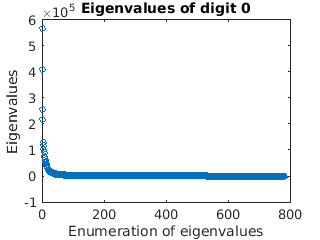

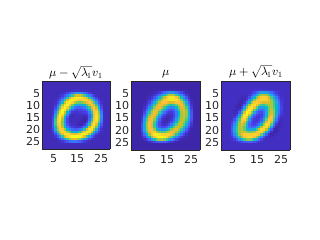

##### for digit 1


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 511989.5257 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


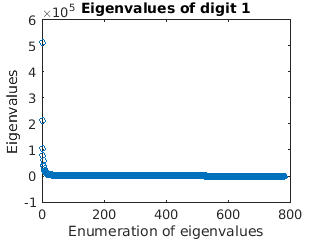

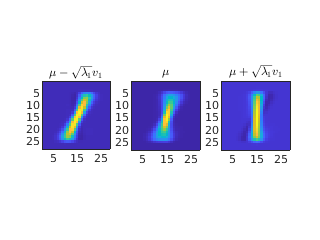

##### for digit 2


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 396868.5146 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


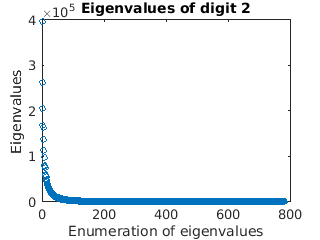

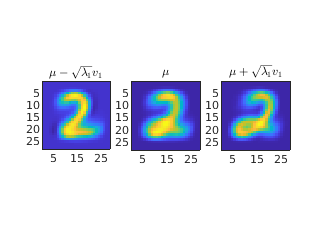

##### for digit 3


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 364424.8968 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


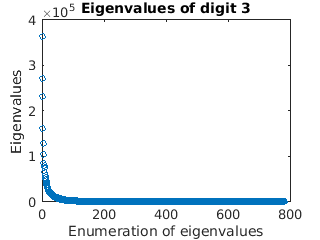

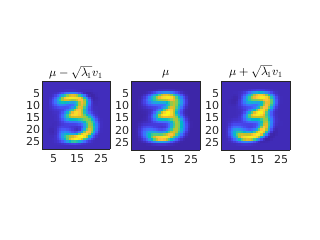

##### for digit 4


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 317142.6202 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


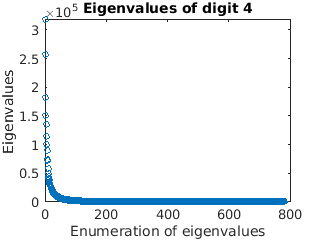

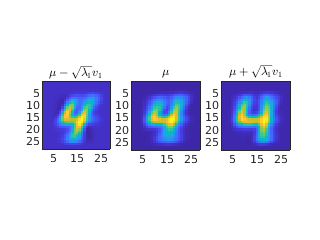

##### for digit 5


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 517409.1325 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


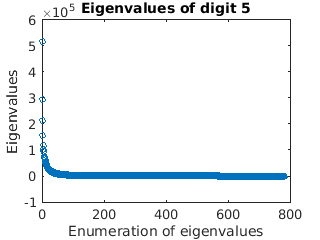

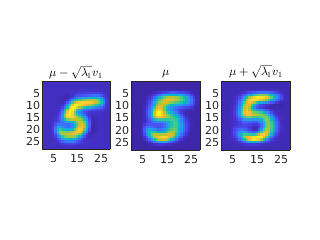

##### for digit 6


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 485385.8571 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


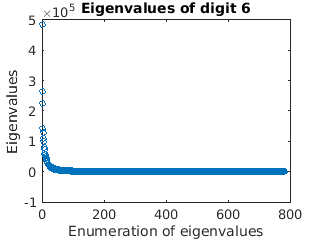

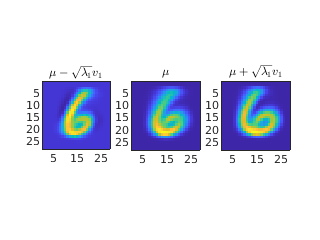

##### for digit 7


Mean :


ans =          0
         0
         0
         0
         0
         0
         0
    0.0075
    0.0305
    0.0466


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 391852.9004 and PCA : 


ans =          0
         0
         0
         0
         0
         0
         0
    0.0000
    0.0001
    0.0000


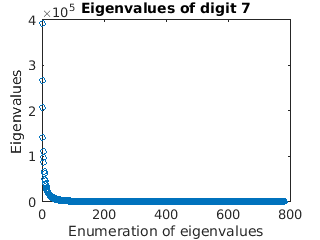

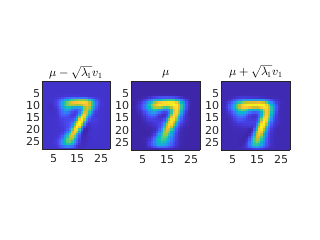

##### for digit 8


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 366328.2645 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


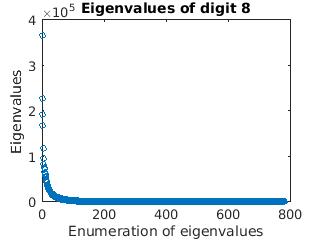

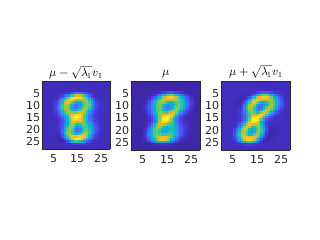

##### for digit 9


Mean :


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Covariance :


ans = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Eigenvalue = 403292.04 and PCA : 


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


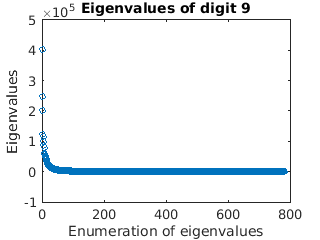

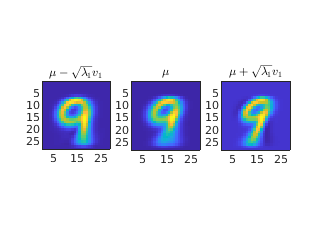

t = 0:1:783;
for i = 1:1:10
    disp("##### for digit " + (i-1));
    disp("Mean :"); % displaying mean
    mu(:, i)
    disp("Covariance :"); % displaying covariance matrix
    cov(:,:,i) 
    disp("Eigenvalue = " + eigen_vals(1, i) + " and PCA : "); % displaying principal mode of variation
    eigen_vecs(:,i)

    figure,
    plot(t, eigen_vals(:,i), "o", 'MarkerSize',5); % plotting of eigenvalues
    title("Eigenvalues of digit " + (i-1));
    ylabel("Eigenvalues");
    xlabel("Enumeration of eigenvalues");

    figure, % displaying of 3 images side-by-side
    subplot(1,3,1), imagesc(reshape(mu(:,i)-eigen_vecs(:,i)*sqrt(eigen_vals(1,i)), 28, 28));
    title('$\mu - \sqrt{\lambda_{1}}v_{1}$','interpreter','latex');
    pbaspect([1,1,1]);
    subplot(1,3,2), imagesc(reshape(mu(:,i), 28, 28));
    title('$\mu $','interpreter','latex');
    pbaspect([1,1,1]);
    subplot(1,3,3), imagesc(reshape(mu(:,i)+eigen_vecs(:,i)*sqrt(eigen_vals(1,i)), 28, 28));
     title('$\mu + \sqrt{\lambda_{1}}v_{1}$','interpreter','latex');
     pbaspect([1,1,1]);
end